# **Week L0: Single-Carrier with Alamouti Coding**

This script implements a simplified optic fibre communications system using Alamouti coding

## **Transmitter**

The model of the transmitter consists of the following elements:

- A symbol generator which modulates source bits using QPSK

- A pulse shaper which creates an electrical signal using the generated symbols

- An IQ modulator which modulates the output of a laser ac cording to an electrical signal

### Alamouti Coding

clearvars

% Parameters
NSymb = 300000; % No. of symbols 
SpS = 2; % Samples per symbol
Rs = 50e9; % Symbol rate in symbols/sec
T = 1/(SpS*Rs); % Sampling period in s
t= [0:1:NSymb*SpS - 1]*T; % Time vector for plotting time-series data

voltageLevelsQPSK = [asin(-1/sqrt(2)), asin(1/sqrt(2))]'; % Discrete voltages for QAM
voltageLevelsQAM = [asin(-3/sqrt(10)), asin(-1/sqrt(10)), asin(1/sqrt(10)), asin(3/sqrt(10))]';
DCOffset = 0; % DC offset of modulated current in V

% --------------------------------------------------------------------------------------

% FOR QPSK:
% Generating random bit sequence(s)
sourceBitsQPSK = randi([0 1], NSymb*2, 1); % Matrix of source bits for QPSK
sourceIntsQPSK = bit2int(sourceBitsQPSK, 2); % Vector of source bits converted to ints
sourceSymbolsQPSK = pskmod(sourceIntsQPSK, 4, pi/4); % Maps source bit vector to symbol vector
codedSymbolsQPSK = AlamoutiCoding(sourceSymbolsQPSK); % Encodes symbols using Alamouti coding

% Modulating voltage with generated symbols
% vI_QPSK = ones(size(codedSymbolsQPSK)); vQ_QPSK = zeros(size(codedSymbolsQPSK));
% vI_QPSK(real(codedSymbolsQPSK)>0) = voltageLevelsQPSK(2); % Maps 1 -> asin(1/sqrt(2))
% vI_QPSK(real(codedSymbolsQPSK)<0) = voltageLevelsQPSK(1); % Maps -1 -> asin(-1/sqrt(2))
% vQ_QPSK(imag(codedSymbolsQPSK)>0) = voltageLevelsQPSK(2); % Maps 1 -> asin(1/sqrt(2))
% vQ_QPSK(imag(codedSymbolsQPSK)<0) = voltageLevelsQPSK(1); % Maps -1 -> asin(-1/sqrt(2))

vI_QPSK = real(codedSymbolsQPSK);
vQ_QPSK = imag(codedSymbolsQPSK);

vI_QPSK_upsampled = repelem(vI_QPSK, SpS, 1); % Upsampling according to SpS
vQ_QPSK_upsampled = repelem(vQ_QPSK, SpS, 1); % Upsampling according to SpS

% Visualising in-phase and quadrature voltage
% stairs(t(1:10*SpS), vI_QPSK_upsampled(1:10*SpS,1), "o-");
% hold on
% stairs(t(1:10*SpS), vQ_QPSK_upsampled(1:10*SpS,1), "o-");
% title("Modulated Voltage for QPSK")
% xlabel("Time / s")
% ylabel("Voltage / V")
% legend("In-phase", "Quadrature")
% grid on
% hold off

### Pulse Shaping

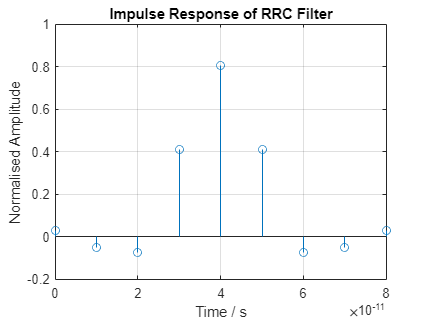

% RRC filter parameters
filterSpan = 4; % Span of RRC filter in no. of symbols
rollOff = 0.5;
filterResponse = rcosdesign(rollOff, filterSpan, SpS)';
samples = 1+(NSymb-1)*SpS + filterSpan*SpS;
v_shaped_t = [0:1:samples-1]*T;

% Visualisation of RRC filter
filterResponse_t = [0:1:filterSpan*SpS]*T; % time vector for the filter response
% filterResponse_t_interp = [0:0.25:filterSpan*SpS]*T;
% filterResponse_interp = interp1(filterResponse_t, filterResponse, filterResponse_t_interp, "spline");
% plot(filterResponse_t, filterResponse, "o", filterResponse_t_interp, filterResponse_interp, ":.");

stem(filterResponse_t, filterResponse, '-o');
title('Impulse Response of RRC Filter');
xlabel('Time / s');
ylabel('Normalised Amplitude');
grid on

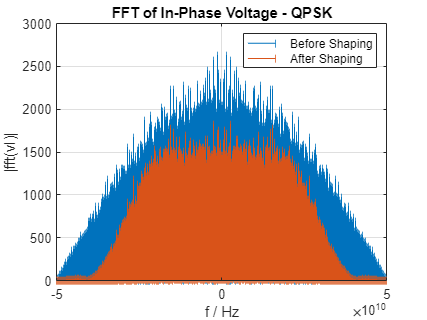


% ---------------------------------------------------------------------------

% FOR QPSK:
% Using RRC filter to shape vI and vQ

vI_QPSK_shaped = upfirdn(vI_QPSK, filterResponse, SpS, 1); vQ_QPSK_shaped = upfirdn(vQ_QPSK, filterResponse, SpS, 1);

% Frequency spectrum of voltage waveforms before filtering
fft_vI_QPSK = fftshift(fft(vI_QPSK_upsampled(:,1))); % FFT of noisy signal before shaping
freqArr = [-NSymb*SpS/2:NSymb*SpS/2 - 1]/(T*NSymb*SpS);

fft_vI_QPSK_shaped = fftshift(fft(vI_QPSK_shaped(:,1))); % FFT of nosiy signal after shaping
freqArr_shaped = [-samples/2:samples/2 - 1]/(T*samples);

stem(freqArr, abs(fft_vI_QPSK), "|");
hold on
stem(freqArr_shaped, abs(fft_vI_QPSK_shaped), "|");
title("FFT of In-Phase Voltage - QPSK");
xlabel("f / Hz");
ylabel("|fft(vI)|");
legend("Before Shaping", "After Shaping");
hold off
grid on


% Visualising pulse-shaped voltages
% stairs(v_shaped_t(1:10*SpS + filterSpan), vI_QPSK_upsampled(1:10*SpS + filterSpan,1), "o-");
% hold on
% plot(v_shaped_t(1:10*SpS + filterSpan), vI_QPSK_shaped(1:10*SpS + filterSpan,1), "o-");
% title("Shaped In-Phase Voltage - QPSK");
% ylabel("Voltage / V");
% xlabel('Time / s');
% legend("Before shaping", "After shaping");
% grid on
% hold off

bandwidth = 0.5*(1+rollOff)/T

bandwidth = 7.5000e+10

### IQ Modulation

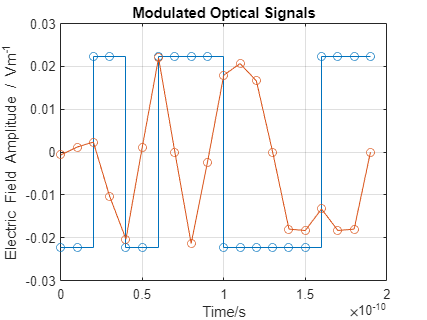

% Initialising laser parameters
lineWidth = 0;
laserPw_dBm = 0;
laserPw_Lin = 1e-3*10^(laserPw_dBm/10);

% Generating output from laser modelled as a continuous-wave source
laserE = Laser(laserPw_dBm, lineWidth, SpS, Rs, NSymb, 1); % Laser output to be used with unshaped signals
laserE_shaped = Laser(laserPw_dBm, lineWidth, SpS, Rs, samples/SpS, 1); % Laser output to be used with shaped signals

% Visualising output from laser
% plot(t(1:20), real(laserE(1:20)), "o-");
% title("Laser Output as a Continous Wave");
% xlabel("Time/s")
% ylabel("Electric Field Amplitude / Vm^{-1}");
% grid on

% Modulating optical signal using IQM
Vpi = pi/2; % Voltge required to change phase of E-field by pi

% Unshaped Signals
modOpticSigQPSK = (vI_QPSK_upsampled+1i*vQ_QPSK_upsampled).*laserE;
modOpticSigQPSK_shaped = (vI_QPSK_shaped+1i*vQ_QPSK_shaped).*laserE_shaped;

% Visualising modulated optical signals
stairs(t(1:10*SpS), real(modOpticSigQPSK(1:10*SpS,1)), "o-");
hold on
plot(t(1:10*SpS), real(modOpticSigQPSK_shaped(1:10*SpS,1)), "o-");
title("Modulated Optical Signals")
xlabel("Time/s")
ylabel("Electric Field Amplitude / Vm^{-1}")
grid on
hold off

## Optical Channel

% Inserting CD
D = 17; % Group velocity dispersion in ps/nm/km
CLambda = 1550e-9; % Central wavelength of optical carrier in m
linkLength = 50e3; % Fibre link length in m

channelOutQPSK_CD = CDInsertion(modOpticSigQPSK, SpS, Rs, D, CLambda, linkLength, 2); 
channelOutQPSK_shaped_CD = CDInsertion(modOpticSigQPSK_shaped, SpS, Rs, D, CLambda, linkLength, 2); 

% Inserting rotations
% thetaArr = [0 85];
% modOpticSigQPSK_rot = zeros(size(modOpticSigQPSK,1), size(modOpticSigQPSK,2), length(thetaArr));
% for i=1:size(thetaArr,2)
%     modOpticSigQPSK_rot(:,:,i) = PolRotate(channelOutQPSK_CD, thetaArr(i), 0);
% end

theta = 0; phi = 0;
modOpticSigQPSK_shaped = PolRotate(modOpticSigQPSK_shaped, theta, phi);

% Debugging addition of CD through immediate CD compensation

% channelOutQPSK_shaped_CD_filtered = upfirdn(channelOutQPSK_shaped_CD(:,1), filterResponse, 1, SpS);
% channelOutQPSK_shaped_CD_filtered = channelOutQPSK_shaped_CD_filtered(filterSpan+1:end-filterSpan);
% 
% debugCDC = OverlapSaveCDC(channelOutQPSK_CD(:,1),D,linkLength,CLambda,Rs,1,SpS,2^8,50);
% debugCDC_shaped = OverlapSaveCDC(channelOutQPSK_shaped_CD_filtered,D,linkLength,CLambda,Rs,1,1,2^8,50);

% Evaluating BER when CDC is applied after filtering
% debugCDC_shaped_filtered = debugCDC_shaped;
% debugCDC_shaped_filtered(2:2:end) = -conj(debugCDC_shaped_filtered(2:2:end));
% 
% debugCDC_shaped_filtered_Ints = pskdemod(debugCDC_shaped_filtered, 4, pi/4);
% debugCDC_shaped_filtered_Bits = int2bit(debugCDC_shaped_filtered_Ints, 2);
% [~, BER_debugCDC_shaped] = biterr(debugCDC_shaped_filtered_Bits, sourceBitsQPSK)

% Evaluating BER when CDC is applied before filtering
% debugCDC_shaped_filtered = upfirdn(debugCDC_shaped, filterResponse, 1, SpS);
% debugCDC_shaped_filtered = debugCDC_shaped_filtered(filterSpan+1:end-filterSpan);
% debugCDC_shaped_filtered(2:2:end) = -conj(debugCDC_shaped_filtered(2:2:end));
% 
% debugCDC_shaped_filtered_Ints = pskdemod(debugCDC_shaped_filtered, 4, pi/4);
% debugCDC_shaped_filtered_Bits = int2bit(debugCDC_shaped_filtered_Ints, 2);
% [~, BER_debugCDC_shaped] = biterr(debugCDC_shaped_filtered_Bits, sourceBitsQPSK)

% Visualising symbol distributions
% plot(channelOutQPSK_CD(:,1), ".");
% hold on
% plot(debugCDC, ".");
% plot(modOpticSigQPSK(:,1), '+', Linewidth=2);
% title("Distorted Symbol Distribution with CD - Unshaped");
% xlabel("Real")
% ylabel("Imaginary")
% legend("Before CD comp.", "After CD comp.", "Original")
% grid on
% hold off
% 
% plot(channelOutQPSK_shaped_CD(:,1), ".");
% hold on
% plot(debugCDC_shaped, ".");
% plot(modOpticSigQPSK_shaped(:,1), '.', Linewidth=2);
% title("Distorted Symbol Distribution with CD - Unshaped");
% xlabel("Real")
% ylabel("Imaginary")
% legend("Before CD comp.", "After CD comp.", "Original")
% grid on
% hold off

### Adding AWGN

% Adding AWGN to the voltage waveforms before pulse shaping

SNRb_dB = [0:2:8]; % SNR per bit in dB

powerPerSymb = mean(voltageLevelsQPSK.^2);
powerPerBit= powerPerSymb/2;

SNRb_Lin = 10.^(SNRb_dB/10); % linear SNR per symbol
AWGN_StdDev = sqrt(powerPerSymb./SNRb_Lin); % AWGN Standard deviation

channelOutQPSK_AWGN = zeros(size(modOpticSigQPSK,1), size(modOpticSigQPSK,2), length(SNRb_dB));
channelOutQPSK_AWGN_CD = zeros(size(channelOutQPSK_CD,1), size(channelOutQPSK_CD,2), length(SNRb_dB));
channelOutQPSK_shaped_AWGN = zeros(size(modOpticSigQPSK_shaped,1), size(modOpticSigQPSK_shaped,2), length(SNRb_dB));
channelOutQPSK_shaped_AWGN_CD = zeros(size(channelOutQPSK_shaped_CD,1), size(channelOutQPSK_shaped_CD,2), length(SNRb_dB));

noisePw = zeros(1,length(SNRb_dB)); noisePw_shaped = zeros(1,length(SNRb_dB));
noisePw_CD = zeros(1,length(SNRb_dB)); noisePw_shaped_CD = zeros(1,length(SNRb_dB));

for i=1:length(SNRb_dB)
%      [channelOutQPSK_AWGN(:,:,i), noisePw(1,i)] = awgn(modOpticSigQPSK, convertSNR(SNRb_dB(i),'ebno', samplespersymbol=1, bitspersymbol=2), 'measured');
%      [channelOutQPSK_AWGN_CD(:,:,i), noisePw_CD(1,i)] = awgn(channelOutQPSK_CD, convertSNR(SNRb_dB(i),'ebno', samplespersymbol=1, bitspersymbol=2), 'measured');
     [channelOutQPSK_shaped_AWGN(:,:,i), noisePw_shaped(1,i)] = awgn(modOpticSigQPSK_shaped, convertSNR(SNRb_dB(i),'ebno', samplespersymbol=2, bitspersymbol=2), 'measured');
     [channelOutQPSK_shaped_AWGN_CD(:,:,i), noisePw_shaped_CD(1,i)] = awgn(channelOutQPSK_shaped_CD, convertSNR(SNRb_dB(i),'ebno', samplespersymbol=2, bitspersymbol=2), 'measured');
end

% Debugging AWGN addition

% sigPw = var(modOpticSigQPSK(:,1),0,1)
% sigPw_shaped = var(modOpticSigQPSK_shaped(:,1),0,1)
% 
% noisePw
% noisePw_shaped
% debugSNR = 10*log10(sigPw./noisePw) - 10*log10(2)
% debugSNR_shaped = 10*log10(sigPw_shaped./noisePw_shaped) - 10*log10(2)
% 
% sigPw_CD = var(channelOutQPSK_CD(:,1),0,1)
% sigPw_shaped_CD = var(channelOutQPSK_shaped_CD(:,1),0,1)
% 
% noisePw_CD
% noisePw_shaped_CD
% debugSNR_CD = 10*log10(sigPw_CD./noisePw_CD) - 10*log10(2)
% debugSNR_shaped_CD = 10*log10(sigPw_shaped./noisePw_shaped_CD) - 10*log10(2)
% 
% %--------------------------------------------------------------------------------
% 
% % Visualising in-phase voltage with and without noise
% stairs(t(1:10*SpS), real(modOpticSigQPSK(1:10*SpS,1)), '-o');
% hold on
% stairs(t(1:10*SpS), real(channelOutQPSK_AWGN(1:10*SpS,1)), '-o');
% title("In-Phase Electric Field");
% xlabel("Time / s");
% ylabel("Electric Field / Vm^{-1}");
% legend("Without AWGN", "With AWGN");
% grid on
% hold off
% 
% % Visualising Symbol Distribution
% plot(channelOutQPSK_AWGN(:,1,1), '.');
% hold on
% plot(channelOutQPSK_AWGN(:,1,end), '.');
% plot(sourceSymbolsQPSK(:,1)*sqrt(laserPw_Lin), '+', Linewidth=2);
% title("Symbol Distribution with AWGN");
% xlabel("real");
% ylabel("Imaginary")
% grid on
% hold off
% 
% BERQPSK_AWGN_test = zeros(1,length(SNRb_dB)); BERQPSK_shaped_AWGN_test = zeros(1,length(SNRb_dB));
% channelOutQPSK_test = channelOutQPSK_AWGN(1:SpS:end,1,:); channelOutQPSK_test(2:2:end,1,:) = -1*conj(channelOutQPSK_test(2:2:end,1,:));
% 
% channelOutQPSK_reshaped = reshape(channelOutQPSK_shaped_AWGN(:,1,:),samples,size(channelOutQPSK_shaped_AWGN,3),1);
% channelOutQPSK_shaped_test = upfirdn(channelOutQPSK_reshaped, filterResponse, 1, SpS); 
% channelOutQPSK_shaped_test = channelOutQPSK_shaped_test(filterSpan+1 : end-filterSpan,:,:);
% channelOutQPSK_shaped_test(2:2:end,:) = -1*conj(channelOutQPSK_shaped_test(2:2:end,:));
% 
% for i=1:length(SNRb_dB)
%     IntsQPSK_AWGN_test = pskdemod(channelOutQPSK_test(:,1,i), 4, pi/4);
%     BitsQPSK_AWGN_test = int2bit(IntsQPSK_AWGN_test, 2);
%     [~, BERQPSK_AWGN_test(1,i)] = biterr(BitsQPSK_AWGN_test, sourceBitsQPSK);
% 
%     IntsQPSK_shaped_AWGN_test = pskdemod(channelOutQPSK_shaped_test(:,i,1), 4, pi/4);
%     BitsQPSK_shaped_AWGN_test = int2bit(IntsQPSK_shaped_AWGN_test, 2);
%     [~, BERQPSK_shaped_AWGN_test(1,i)] = biterr(BitsQPSK_shaped_AWGN_test, sourceBitsQPSK);
% end
% 
% semilogy(SNRb_dB, 0.5*erfc(sqrt(10.^(SNRb_dB/10))));
% hold on
% semilogy(SNRb_dB, BERQPSK_AWGN_test', '*');
% semilogy(SNRb_dB, BERQPSK_shaped_AWGN_test', '*');
% title("BER vs. SNR for QPSK");
% ylabel("BER");
% xlabel("SNR per bit / dB");
% legend("Theoretical", "Unshaped", "Shaped");
% grid on
% hold off

### Optical Front-End

% Generating Local optical signal for coherent detection
% carr_freq = 3e8/(1550e-9); % Carrier frequency in ms-1
% freq_offset = 0; % LO signal frequency offset

Elo = Laser(laserPw_dBm, lineWidth, SpS, Rs, NSymb, 1); % LO signal with non-zero linewidth for unshaped signals
Elo_shaped = Laser(laserPw_dBm, lineWidth, SpS, Rs, samples/SpS, 1); % LO signal with non-zero linewidth for shaped signals
% Elo_shifted = LOFrequencyShift(Elo, freq_offset, T); % Frequency-shifted LO signal for unshaped information signal
% Elo_shaped_shifted = LOFrequencyShift(Elo_shaped, freq_offset, T); % Frequency-shifted LO signal for shaped information signal

% Visualising locally generated optical signal
% plot(t(1:20), real(Elo(1:20,1)), "-o");
% hold on
% plot(t(1:20), real(Elo_shifted(1:20,1)), "-o");
% title("Locally Generated Optical Signal");
% xlabel("Time/s")
% ylabel("Electric Field Amplitude/ Vm^{-1}")
% legend("Ideal", "Frequency-Shifted")
% hold off
% grid on

% Visualising FFTs of original and frequency shifted LO laser signal
% fft_Elo = fftshift(fft(Elo(:,1))); % FFT of original LO signal
% fft_Elo_shifted = fftshift(fft(real(Elo_shifted(:,1)))); % FFT of frequency-shifted LO signal
% freqArr_Elo = [-NSymb*SpS/2:NSymb*SpS/2 - 1]/(T*NSymb*SpS);

% stem(freqArr_Elo, abs(fft_Elo), "|");
% hold on
% stem(freqArr_Elo, abs(fft_Elo_shifted), "|");
% title("FFT of LO Signals");
% xlabel("f / Hz");
% ylabel("|fft(Elo)|");
% legend("Matched signal", "Frequency-shifted signal");
% hold off
% grid on

% ---------------------------------------------------------------------------------------

% Generating output from optical front-end
eta_ph = 1; % Responsivity of photodetectors

% WITHOUT AWGN
OpticFEOutQPSK = OpticalFrontEnd(modOpticSigQPSK, [Elo Elo], eta_ph, 2); % Unshaped
OpticFEOutQPSK_CD = OpticalFrontEnd(channelOutQPSK_CD, [Elo Elo], eta_ph, 2); % Unshaped + CD
OpticFEOutQPSK_shaped = OpticalFrontEnd(modOpticSigQPSK_shaped, [Elo_shaped Elo_shaped], eta_ph, 2); % Shaped
OpticFEOutQPSK_shaped_CD = OpticalFrontEnd(channelOutQPSK_shaped_CD, [Elo_shaped Elo_shaped], eta_ph, 2); % Shaped + CD

% Unshaped + rotation
% OpticFEOutQPSK_rot = zeros(size(modOpticSigQPSK_rot,1), 2*size(modOpticSigQPSK_rot,2),size(modOpticSigQPSK_rot,3));
% for i=1:size(modOpticSigQPSK_rot,3)
%     OpticFEOutQPSK_rot(:,:,i) = OpticalFrontEnd(modOpticSigQPSK_rot(:,:,i), [Elo Elo], eta_ph, 2);
% end

% WITH AWGN
% OpticFEOutQPSK_AWGN = zeros(size(channelOutQPSK_AWGN,1), 4, length(SNRb_dB));
% OpticFEOutQPSK_AWGN_CD = zeros(size(channelOutQPSK_AWGN_CD,1), 4, length(SNRb_dB));
OpticFEOutQPSK_shaped_AWGN = zeros(size(channelOutQPSK_shaped_AWGN,1), 4, length(SNRb_dB));
OpticFEOutQPSK_shaped_AWGN_CD = zeros(size(channelOutQPSK_shaped_AWGN_CD,1), 4, length(SNRb_dB));

for i=1:length(SNRb_dB)
%     OpticFEOutQPSK_AWGN(:,:,i) = OpticalFrontEnd(channelOutQPSK_AWGN(:,:,i), [Elo Elo], eta_ph, 2); % Unshaped + AWGN
%     OpticFEOutQPSK_AWGN_CD(:,:,i) = OpticalFrontEnd(channelOutQPSK_AWGN_CD(:,:,i), [Elo Elo], eta_ph, 2); % Unshaped + AWGN + CD
    OpticFEOutQPSK_shaped_AWGN(:,:,i) = OpticalFrontEnd(channelOutQPSK_shaped_AWGN(:,:,i), [Elo_shaped Elo_shaped], eta_ph, 2); % Shaped + AWGN
    OpticFEOutQPSK_shaped_AWGN_CD(:,:,i) = OpticalFrontEnd(channelOutQPSK_shaped_AWGN_CD(:,:,i), [Elo_shaped Elo_shaped], eta_ph, 2); % Shaped + AWGN + CD
end

% ---------------------------------------------------------------------------------------

% TIA amplification and sampling using ADC
TIA_Gain = 1; % TIA amplification factor
Fs = SpS; % Sampling frequency of ADC

% Amplification and separation of in-phase and quadrature components of the two polarizations
% QPSK
% WITHOUT AWGN
OpticFEOutQPSK_I = TIA_Gain*OpticFEOutQPSK(:,1:2:end); OpticFEOutQPSK_Q = TIA_Gain*OpticFEOutQPSK(:,2:2:end); % Unshaped 
OpticFEOutQPSK_CD_I = TIA_Gain*OpticFEOutQPSK_CD(:,1:2:end); OpticFEOutQPSK_CD_Q = TIA_Gain*OpticFEOutQPSK_CD(:,2:2:end); % Unshaped + CD
% OpticFEOutQPSK_rot_I = TIA_Gain*OpticFEOutQPSK_rot(:,1:2:end,:); OpticFEOutQPSK_rot_Q = TIA_Gain*OpticFEOutQPSK_rot(:,2:2:end,:); % Unshaped + rotated
OpticFEOutQPSK_shaped_I = TIA_Gain*OpticFEOutQPSK_shaped(:,1:2:end); OpticFEOutQPSK_shaped_Q = TIA_Gain*OpticFEOutQPSK_shaped(:,2:2:end); % Shaped 
OpticFEOutQPSK_shaped_CD_I = TIA_Gain*OpticFEOutQPSK_shaped_CD(:,1:2:end); OpticFEOutQPSK_shaped_CD_Q = TIA_Gain*OpticFEOutQPSK_shaped_CD(:,2:2:end); % Shaped + CD

% WITH AWGN
% OpticFEOutQPSK_AWGN_I = TIA_Gain*OpticFEOutQPSK_AWGN(:,1:2:end,:); OpticFEOutQPSK_AWGN_Q = TIA_Gain*OpticFEOutQPSK_AWGN(:,2:2:end,:); % Unshaped + AWGN
% OpticFEOutQPSK_AWGN_CD_I = TIA_Gain*OpticFEOutQPSK_AWGN_CD(:,1:2:end,:); OpticFEOutQPSK_AWGN_CD_Q = TIA_Gain*OpticFEOutQPSK_AWGN_CD(:,2:2:end,:); % Unshaped + AWGN + CD
OpticFEOutQPSK_shaped_AWGN_I = TIA_Gain*OpticFEOutQPSK_shaped_AWGN(:,1:2:end,:); OpticFEOutQPSK_shaped_AWGN_Q = TIA_Gain*OpticFEOutQPSK_shaped_AWGN(:,2:2:end,:); % Shaped + AWGN
OpticFEOutQPSK_shaped_AWGN_CD_I = TIA_Gain*OpticFEOutQPSK_shaped_AWGN_CD(:,1:2:end,:); OpticFEOutQPSK_shaped_AWGN_CD_Q = TIA_Gain*OpticFEOutQPSK_shaped_AWGN_CD(:,2:2:end,:); % Shaped + AWGN + CD

% Debuggin optical front-end
% plot(t(1:10*SpS), real(channelOutQPSK_shaped_AWGN_CD(1:10*SpS,1,1)), "-o")
% hold on
% plot(t(1:10*SpS), 100*OpticFEOutQPSK_shaped_AWGN_CD_I(1:10*SpS,1,1), "-o")
% title("Comparison of Channel Output with Optic-Front End")
% xlabel("Time / s")
% ylabel("Value")
% legend("Channel Output", "Optic Front-End Output")
% hold off
% grid on

## DSP

### Scaling 

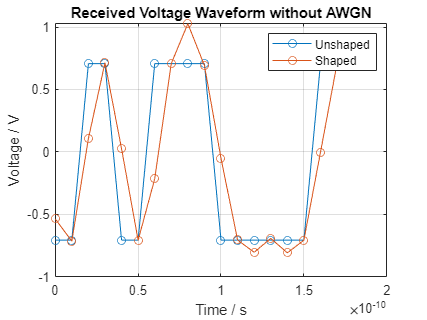

% Scaling factor between output of IQM and output of optical front-end
laserEMag = sqrt(laserPw_Lin);
% scaleFactor=1;
scaleFactor = TIA_Gain*eta_ph*laserEMag*laserEMag;

% Cancelling the scaling factor and downsampling:
% QPSK
% WITHOUT AWGN
voltageQPSK_I = OpticFEOutQPSK_I/scaleFactor; voltageQPSK_Q = OpticFEOutQPSK_Q/scaleFactor; % Unshaped 
voltageQPSK_CD_I = OpticFEOutQPSK_CD_I/scaleFactor; voltageQPSK_CD_Q = OpticFEOutQPSK_CD_Q/scaleFactor; % Unshaped + CD
% voltageQPSK_rot_I = OpticFEOutQPSK_rot_I/scaleFactor; voltageQPSK_rot_Q = OpticFEOutQPSK_rot_Q/scaleFactor; % Unshaped + rot

voltageQPSK_shaped_I = upfirdn(OpticFEOutQPSK_shaped_I/scaleFactor, filterResponse, 1, 1); voltageQPSK_shaped_I = voltageQPSK_shaped_I(filterSpan*SpS:end - filterSpan*SpS,:); % Shaped 
voltageQPSK_shaped_Q = upfirdn(OpticFEOutQPSK_shaped_Q/scaleFactor, filterResponse, 1, 1); voltageQPSK_shaped_Q = voltageQPSK_shaped_Q(filterSpan*SpS:end - filterSpan*SpS,:); % Shaped 

plot(t(1:SpS*10), voltageQPSK_I(1:SpS*10,1), "-o");
hold on
plot(t(1:SpS*10), voltageQPSK_shaped_I(1:SpS*10,1), "-o");
title("Received Voltage Waveform without AWGN");
xlabel("Time / s")
ylabel("Voltage / V")
legend("Unshaped", "Shaped")
grid on
hold off


voltageQPSK_shaped_CD_I = OpticFEOutQPSK_shaped_CD_I/scaleFactor; % Shaped + CD
voltageQPSK_shaped_CD_Q = OpticFEOutQPSK_shaped_CD_Q/scaleFactor; % Shaped + CD

% WITH AWGN
% voltageQPSK_AWGN_I = OpticFEOutQPSK_AWGN_I/scaleFactor; voltageQPSK_AWGN_Q = OpticFEOutQPSK_AWGN_Q/scaleFactor; % Unshaped 
% voltageQPSK_AWGN_CD_I = OpticFEOutQPSK_AWGN_CD_I/scaleFactor; voltageQPSK_AWGN_CD_Q = OpticFEOutQPSK_AWGN_CD_Q/scaleFactor; % Unshaped + CD

for i=1:length(SNRb_dB)
    voltageQPSK_shaped_AWGN_I(:,:,i) = upfirdn(OpticFEOutQPSK_shaped_AWGN_I(:,:,i)/scaleFactor, filterResponse, 1, SpS); 
    voltageQPSK_shaped_AWGN_Q(:,:,i) = upfirdn(OpticFEOutQPSK_shaped_AWGN_Q(:,:,i)/scaleFactor, filterResponse, 1, SpS); 
end
voltageQPSK_shaped_AWGN_I = voltageQPSK_shaped_AWGN_I(filterSpan+1:end-filterSpan,:,:); % Shaped 
voltageQPSK_shaped_AWGN_Q = voltageQPSK_shaped_AWGN_Q(filterSpan+1:end-filterSpan,:,:); % Shaped 

voltageQPSK_shaped_AWGN_CD_I = OpticFEOutQPSK_shaped_AWGN_CD_I/scaleFactor;
voltageQPSK_shaped_AWGN_CD_Q = OpticFEOutQPSK_shaped_AWGN_CD_Q/scaleFactor;

% plot(t(1:SpS*10), voltageQPSK_shaped_CD_I(1:SpS*10,1), "-o");
% hold on
% plot(t(1:SpS*10), voltageQPSK_shaped_AWGN_CD_I(1:SpS*10,1), "-o");
% title("Received Voltage Waveform with AWGN");
% xlabel("Time / s")
% ylabel("Voltage / V")
% legend("Unshaped", "Shaped")
% grid on
% hold off

% plot(OpticFEOutQPSK_CD_I(:,1,end) ,OpticFEOutQPSK_CD_Q(:,1,end), ".", lineWidth=3);
% hold on
% plot(OpticFEOutQPSK_shaped_CD_I(:,1,end) ,OpticFEOutQPSK_shaped_CD_Q(:,1,end), ".", lineWidth=3);
% title("Distorted Symbol Distribution");
% xlabel("Real")
% ylabel("Imaginary")
% legend("Unshaped", "Shaped")
% grid on
% hold off

### Overlap and Save (CDC)

% Applying the overlap and save method for CD compensation

% CD Compensation
c = 299792458; % Speed of light in m/s
N_CD = ceil(6.67*(D*1e-6)*(CLambda^2)*linkLength*(Rs^2)*SpS/(2*pi*c)) % CD Equalizer Length#

N_CD = 37

N_CD = 50

N_CD = 50

N_FFT = 2^9;

% WITHOUT AWGN
voltageQPSK_CDC = OverlapSaveCDC(voltageQPSK_CD_I(:,1)+1i*voltageQPSK_CD_Q(:,1), D, linkLength, CLambda, Rs, 1, SpS, N_FFT, N_CD);

voltageQPSK_shaped_CDC = OverlapSaveCDC(voltageQPSK_shaped_CD_I(:,1)+1i*voltageQPSK_shaped_CD_Q(:,1), D, linkLength, CLambda, Rs, 1, SpS, N_FFT, N_CD);


% WITH AWGN
% voltageQPSK_AWGN_CDC = zeros(size(voltageQPSK_AWGN_CD_I,1), length(SNRb_dB));

voltageQPSK_shaped_AWGN_CDC = zeros(size(voltageQPSK_shaped_AWGN_CD_I,1), length(SNRb_dB));
for i=1:length(SNRb_dB) 
%     voltageQPSK_AWGN_CDC(:,i) = OverlapSaveCDC(voltageQPSK_AWGN_CD_I(:,1,i)+1i*voltageQPSK_AWGN_CD_Q(:,1,i), D, linkLength, CLambda, Rs, 1, SpS, N_FFT, N_CD);
    voltageQPSK_shaped_AWGN_CDC(:,i) = OverlapSaveCDC(voltageQPSK_shaped_AWGN_CD_I(:,1,i)+1i*voltageQPSK_shaped_AWGN_CD_Q(:,1,i), D, linkLength, CLambda, Rs, 1, SpS, N_FFT, N_CD);
end

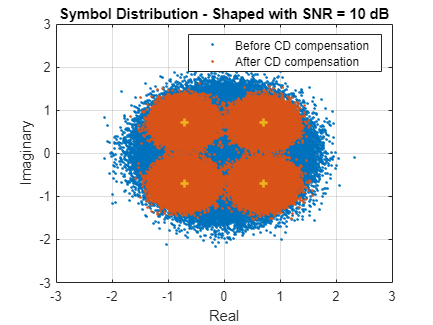


% Matched filtering shaped signals
% Without AWGN
voltageQPSK_shaped_CDC_filtered = upfirdn(real(voltageQPSK_shaped_CDC),filterResponse, 1, SpS)+1i*upfirdn(imag(voltageQPSK_shaped_CDC),filterResponse, 1, SpS);
voltageQPSK_shaped_CDC_filtered = voltageQPSK_shaped_CDC_filtered(filterSpan+1:end-filterSpan);

% WITH AWGN
clear voltageQPSK_shaped_AWGN_CDC_filtered
for i=1:length(SNRb_dB)
    voltageQPSK_shaped_AWGN_CDC_filtered(:,i) = upfirdn(real(voltageQPSK_shaped_AWGN_CDC(:,i)),filterResponse, 1, SpS)+1i*upfirdn(imag(voltageQPSK_shaped_AWGN_CDC(:,i)),filterResponse, 1, SpS);
end

voltageQPSK_shaped_AWGN_CDC_filtered = voltageQPSK_shaped_AWGN_CDC_filtered(filterSpan+1:end-filterSpan,:);

% Visualising constellation before and after CD compensation
% plot(voltageQPSK_CD_I(:,1)+1i*voltageQPSK_CD_Q(:,1), '.');
% hold on
% plot(voltageQPSK_CDC, '.');
% plot(sourceSymbolsQPSK, '+', LineWidth=2);
% title("Symbol Distribution - Unshaped without AWGN")
% xlabel("Real")
% ylabel("Imaginary")
% legend("Before CD compensation", "After CD compensation")
% grid on
% hold off
% 
% plot(voltageQPSK_shaped_CD_I(:,1)+1i*voltageQPSK_shaped_CD_Q(:,1), '.');
% hold on
% plot(voltageQPSK_shaped_CDC, '.');
% plot(sourceSymbolsQPSK, '+', LineWidth=2);
% title("Symbol Distribution - Shaped without AWGN")
% xlabel("Real")
% ylabel("Imaginary")
% legend("Before CD compensation", "After CD compensation")
% grid on
% hold off

% plot(voltageQPSK_CD_I(:,1)+1i*voltageQPSK_CD_Q(:,1), '.');
% hold on
% plot(voltageQPSK_AWGN_CDC(:,end), '.');
% plot(sourceSymbolsQPSK, '+', LineWidth=2);
% title("Symbol Distribution - Unshaped with SNR = 10 dB")
% xlabel("Real")
% ylabel("Imaginary")
% legend("Before CD compensation", "After CD compensation")
% grid on
% hold off

plot(voltageQPSK_shaped_CD_I(:,1)+1i*voltageQPSK_shaped_CD_Q(:,1), '.');
hold on
plot(voltageQPSK_shaped_AWGN_CDC_filtered(:,end), '.');
plot(sourceSymbolsQPSK, '+', LineWidth=2);
title("Symbol Distribution - Shaped with SNR = 10 dB")
xlabel("Real")
ylabel("Imaginary")
legend("Before CD compensation", "After CD compensation")
grid on
hold off


% plot(voltageQPSK_AWGN_CDC(:,1,1), '.');
% hold on
% plot(voltageQPSK_AWGN_CDC(:,1,3), '.');
% plot(voltageQPSK_AWGN_CDC(:,1,5), '.');
% plot(sourceSymbolsQPSK, '+', LineWidth=2);
% title("Symbol Distribution with AWGN")
% xlabel("Real")
% ylabel("Imaginary")
% grid on
% hold off

% New Debugging CD compensation

% Without AWGN
% voltageQPSK_CDC_debug = voltageQPSK_CDC(1:SpS:end); voltageQPSK_CDC_debug(2:2:end) = -conj(voltageQPSK_CDC_debug(2:2:end));
% IntsQPSK_CDC = pskdemod(voltageQPSK_CDC_debug, 4, pi/4);
% BitsQPSK_CDC = int2bit(IntsQPSK_CDC, 2);
% [~, BERQPSK_CDC] = biterr(BitsQPSK_CDC, sourceBitsQPSK)
% 
% voltageQPSK_shaped_CDC_debug = voltageQPSK_shaped_CDC_filtered;
% voltageQPSK_shaped_CDC_debug(2:2:end) = -conj(voltageQPSK_shaped_CDC_debug(2:2:end));
% IntsQPSK_shaped_CDC = pskdemod(voltageQPSK_shaped_CDC_debug, 4, pi/4);
% BitsQPSK_shaped_CDC = int2bit(IntsQPSK_shaped_CDC, 2);
% [~, BERQPSK_shaped_CDC] = biterr(BitsQPSK_shaped_CDC, sourceBitsQPSK)
% 
% % With AWGN
% BERQPSK_AWGN_CDC = zeros(1,length(SNRb_dB)); BERQPSK_shaped_AWGN_CDC = zeros(1,length(SNRb_dB));
% voltageQPSK_AWGN_CDC_debug = voltageQPSK_AWGN_CDC(1:SpS:end,:); voltageQPSK_AWGN_CDC_debug(2:2:end,:) = -conj(voltageQPSK_AWGN_CDC_debug(2:2:end,:)); 
% 
% voltageQPSK_shaped_AWGN_CDC_debug = voltageQPSK_shaped_AWGN_CDC_filtered;
% voltageQPSK_shaped_AWGN_CDC_debug(2:2:end,:) = -conj(voltageQPSK_shaped_AWGN_CDC_debug(2:2:end,:)); 
%     
% for i=1:length(SNRb_dB)
%     IntsQPSK_AWGN_CDC_debug = pskdemod(voltageQPSK_AWGN_CDC_debug(:,i), 4, pi/4);
%     BitsQPSK_AWGN_CDC_debug = int2bit(IntsQPSK_AWGN_CDC_debug, 2);
%     [~, BERQPSK_AWGN_CDC(1,i)] = biterr(BitsQPSK_AWGN_CDC_debug, sourceBitsQPSK);
% 
%     IntsQPSK_shaped_AWGN_CDC_debug = pskdemod(voltageQPSK_shaped_AWGN_CDC_debug(:,i), 4, pi/4);
%     BitsQPSK_shaped_AWGN_CDC_debug = int2bit(IntsQPSK_shaped_AWGN_CDC_debug, 2);
%     [~, BERQPSK_shaped_AWGN_CDC(1,i)] = biterr(BitsQPSK_shaped_AWGN_CDC_debug, sourceBitsQPSK);
% end
% 
% semilogy(SNRb_dB, 0.5*erfc(sqrt(10.^(SNRb_dB/10))));
% hold on
% semilogy(SNRb_dB, BERQPSK_AWGN_CDC, 'o');
% semilogy(SNRb_dB, BERQPSK_shaped_AWGN_CDC, '+');
% title("BER vs. SNR");
% ylabel("BER");
% xlabel("SNR per bit / dB");
% legend("Theoretical", "Unshaped", "Shaped");
% grid on
% hold off

% Old Debugging CD compensation 

% Without AWGN
% voltageQPSK_CDC_debug = voltageQPSK_CDC(1:SpS:end); voltageQPSK_CDC_debug(2:2:end) = -conj(voltageQPSK_CDC_debug(2:2:end));
% IntsQPSK_CDC = pskdemod(voltageQPSK_CDC_debug, 4, pi/4);
% BitsQPSK_CDC = int2bit(IntsQPSK_CDC, 2);
% [~, BERQPSK_CDC] = biterr(BitsQPSK_CDC, sourceBitsQPSK)
% 
% voltageQPSK_shaped_CDC_debug = upfirdn(voltageQPSK_shaped_CDC, filterResponse, 1, SpS); voltageQPSK_shaped_CDC_debug = voltageQPSK_shaped_CDC_debug(filterSpan+1:end-filterSpan);
% voltageQPSK_shaped_CDC_debug(2:2:end) = -conj(voltageQPSK_shaped_CDC_debug(2:2:end));
% IntsQPSK_shaped_CDC = pskdemod(voltageQPSK_shaped_CDC_debug, 4, pi/4);
% BitsQPSK_shaped_CDC = int2bit(IntsQPSK_shaped_CDC, 2);
% [~, BERQPSK_shaped_CDC] = biterr(BitsQPSK_shaped_CDC, sourceBitsQPSK)
% 
% % With AWGN
% BERQPSK_AWGN_CDC = zeros(1,length(SNRb_dB)); BERQPSK_shaped_AWGN_CDC = zeros(1,length(SNRb_dB));
% voltageQPSK_AWGN_CDC_debug = voltageQPSK_AWGN_CDC(1:SpS:end,:); voltageQPSK_AWGN_CDC_debug(2:2:end,:) = -conj(voltageQPSK_AWGN_CDC_debug(2:2:end,:)); 
% 
% clear voltageQPSK_shaped_AWGN_CDC_debug
% for i=1:length(SNRb_dB)
%     voltageQPSK_shaped_AWGN_CDC_debug(:,i) = upfirdn(real(voltageQPSK_shaped_AWGN_CDC(:,i)), filterResponse, 1, SpS); 
%     voltageQPSK_shaped_AWGN_CDC_debug(:,i) = voltageQPSK_shaped_AWGN_CDC_debug(:,i) + 1i*upfirdn(imag(voltageQPSK_shaped_AWGN_CDC(:,i)), filterResponse, 1, SpS); 
% end
% 
% voltageQPSK_shaped_AWGN_CDC_debug = voltageQPSK_shaped_AWGN_CDC_debug(filterSpan+1:end-filterSpan,:);
% voltageQPSK_shaped_AWGN_CDC_debug(2:2:end,:) = -conj(voltageQPSK_shaped_AWGN_CDC_debug(2:2:end,:)); 
%     
% for i=1:length(SNRb_dB)
%     IntsQPSK_AWGN_CDC_debug = pskdemod(voltageQPSK_AWGN_CDC_debug(:,i), 4, pi/4);
%     BitsQPSK_AWGN_CDC_debug = int2bit(IntsQPSK_AWGN_CDC_debug, 2);
%     [~, BERQPSK_AWGN_CDC(1,i)] = biterr(BitsQPSK_AWGN_CDC_debug, sourceBitsQPSK);
% 
%     IntsQPSK_shaped_AWGN_CDC_debug = pskdemod(voltageQPSK_shaped_AWGN_CDC_debug(:,i), 4, pi/4);
%     BitsQPSK_shaped_AWGN_CDC_debug = int2bit(IntsQPSK_shaped_AWGN_CDC_debug, 2);
%     [~, BERQPSK_shaped_AWGN_CDC(1,i)] = biterr(BitsQPSK_shaped_AWGN_CDC_debug, sourceBitsQPSK);
% end
% 
% semilogy(SNRb_dB, 0.5*erfc(sqrt(10.^(SNRb_dB/10))));
% hold on
% semilogy(SNRb_dB, BERQPSK_AWGN_CDC, 'o');
% semilogy(SNRb_dB, BERQPSK_shaped_AWGN_CDC, '+');
% title("BER vs. SNR");
% ylabel("BER");
% xlabel("SNR per bit / dB");
% legend("Theoretical", "Unshaped", "Shaped");
% grid on
% hold off

### Adaptive Equalziation

% Without channel distortion
NTaps = 5; NRemove = 280000; N1 = 75000; Mu_T = 1.5e-5; Mu_DD = Mu_T; Mu_p=0;
% trainSymbsQPSK = codedSymbolsQPSK; % trainSymbsQPSK(2:2:end) = conj(trainSymbsQPSK(2:2:end));
trainSymbsQPSK = sourceSymbolsQPSK;

% WITHOUT AWGN
% Unshaped
% [equalizedSymbsQPSK, pQPSK, w11QPSK, w12QPSK, w21QPSK, w22QPSK, errQPSK] = AdapEqualizerAlamouti(voltageQPSK_I(:,1)+1i*voltageQPSK_Q(:,1), trainSymbsQPSK, SpS, NTaps, Mu_T, Mu_DD, Mu_p, N1, 'QPSK'); % Unshaped
% [equalizedSymbsQPSK_CD, pQPSK_CD, w11QPSK_CD, w12QPSK_CD, w21QPSK_CD, w22QPSK_CD, errQPSK_CD] = AdapEqualizerAlamouti(voltageQPSK_shaped_CDC, trainSymbsQPSK, SpS, NTaps, Mu_T, Mu_DD, Mu_p, N1, 'QPSK'); % Unshaped + CD

% equalizedSymbsQPSK_rot = zeros(NSymb,size(thetaArr,2));
% for i=1:size(thetaArr,2)
%     [equalizedSymbsQPSK_rot(:,i),pQPSK_rot,w11QPSK_rot,w12QPSK_rot,w21QPSK_rot,w22QPSK_rot,errQPSK_rot] = AdapEqualizerAlamouti(voltageQPSK_rot_I(:,1,i)+1i*voltageQPSK_rot_Q(:,1,i), trainSymbsQPSK, SpS, NTaps, Mu_T, Mu_DD, Mu_p, N1, 'QPSK'); % Unshaped + rotation
% end

% Shaped
% [equalizedSymbsQPSK_shaped, pQPSK_shaped, w11QPSK_shaped, w12QPSK_shaped, w21QPSK_shaped, w22QPSK_shaped, errQPSK_shaped] = AdapEqualizerAlamouti(voltageQPSK_shaped_I(:,1)+1i*voltageQPSK_shaped_Q(:,1), trainSymbsQPSK, SpS, NTaps, Mu_T, Mu_DD, Mu_p, N1, 'QPSK'); % Shaped

% WITH AWGN
equalizedSymbsQPSK_AWGN_CD = zeros(NSymb, size(SNRb_dB,1));
equalizedSymbsQPSK_shaped_AWGN_CD = zeros(NSymb, size(SNRb_dB,1));
equalizedSymbsQPSK_shaped = zeros(NSymb, size(SNRb_dB,1));
for i=1:length(SNRb_dB)
%    [equalizedSymbsQPSK_AWGN_CD(:,i), pQPSK_CD, w11QPSK_CD, w12QPSK_CD, w21QPSK_CD, w22QPSK_CD, errQPSK_CD] = AdapEqualizerAlamouti(voltageQPSK_AWGN_CDC(:,i), trainSymbsQPSK, SpS, NTaps, Mu_T, Mu_DD, Mu_p, N1, 'QPSK'); % Unshaped + CD
%     [equalizedSymbsQPSK_shaped_AWGN_CD(:,i), pQPSK_shaped_CD, w11QPSK_shaped_CD, w12QPSK_shaped_CD, w21QPSK_shaped_CD, w22QPSK_shaped_CD, errQPSK_shaped_CD] = AdapEqualizerAlamouti(voltageQPSK_shaped_AWGN_CDC_filtered(:,i), trainSymbsQPSK, 1, NTaps, Mu_T, Mu_DD, Mu_p, N1, 'QPSK'); % Shaped + CD
      [equalizedSymbsQPSK_shaped(:,i), pQPSK_shaped, w11QPSK_shaped, w12QPSK_shaped, w21QPSK_shaped, w22QPSK_shaped, errQPSK_shaped] = AdapEqualizerAlamouti(voltageQPSK_shaped_AWGN_I(:,i)+1i*voltageQPSK_shaped_AWGN_Q(:,i), trainSymbsQPSK, 1, NTaps, Mu_T, Mu_DD, Mu_p, N1, 'QPSK'); % Shaped
end

% Visualising evolution of filter coefficients
% plot([1:size(pQPSK)], w11QPSK', '-');
% title("QPSK Filter Coefficient Variation - w_{11}")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQPSK)], w12QPSK', '-');
% title("QPSK Filter Coefficient Variation - w_{12}")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQPSK)], w21QPSK', '-');
% title("QPSK Filter Coefficient Variation - w_{21}")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQPSK)], w22QPSK', '-');
% title("QPSK Filter Coefficient Variation - w_{22}")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQPSK)], pQPSK, '-');
% title("QPSK p variation")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% stem([1:size(errQPSK(:,1))], abs(errQPSK(:,1)), '-');
% title("QPSK Odd Symbol Error Variation")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% stem([1:size(errQPSK(:,2))], abs(errQPSK(:,2)), '-');
% title("QPSK Even Symbol Error Variation")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot(voltageQPSK_I(:,1)+1i*voltageQPSK_Q(:,1), '.');
% hold on
% title("Symbol Distribution")
% plot(equalizedSymbsQPSK(1:NRemove), '.');
% plot(equalizedSymbsQPSK(NRemove+1:end), '.');
% plot(sourceSymbolsQPSK, '+', LineWidth=2);
% xlabel("Real")
% ylabel("Imaginary")
% legend("Before Equalization", "Training", "DD")
% grid on
% hold off


% ----------------------------------------------------------------------------
% With CD added

% Visualising evolution of filter coefficients
% plot([1:size(pQPSK_shaped_CD)], w11QPSK_shaped_CD', '-');
% title("QPSK Filter Coefficient Variation - w_{11} with CD")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQPSK_shaped_CD)], w12QPSK_shaped_CD', '-');
% title("QPSK Filter Coefficient Variation - w_{12} with CD")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQPSK_shaped_CD)], w21QPSK_shaped_CD', '-');
% title("QPSK Filter Coefficient Variation - w_{21} with CD")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQPSK_shaped_CD)], w22QPSK_shaped_CD', '-');
% title("QPSK Filter Coefficient Variation - w_{22} with CD")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQPSK_shaped_CD)], pQPSK_shaped_CD, '-');
% title("QPSK p variation with CD")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% stem([1:size(errQPSK_shaped_CD(:,1))], abs(errQPSK_shaped_CD(:,1)), '|');
% title("QPSK Odd Symbol Error Variation")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% stem([1:size(errQPSK_shaped_CD(:,2))], abs(errQPSK_shaped_CD(:,2)), '|');
% title("QPSK Even Symbol Error Variation")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot(voltageQPSK_CDC, '.');
% hold on
% title("Symbol Distribution")
% plot(equalizedSymbsQPSK_shaped_AWGN_CD(1:NRemove,1), '.');
% plot(equalizedSymbsQPSK_shaped_AWGN_CD(NRemove+1:end,1), '.');
% plot(sourceSymbolsQPSK, '+', LineWidth=2);
% xlabel("Real")
% ylabel("Imaginary")
% legend("Before Equalization", "Training", "DD")
% grid on
% hold off

% plot(1:NTaps, abs(w11QPSK_CD(:,1)), "-o")
% hold on
% plot(1:NTaps, abs(w12QPSK_CD(:,1)), "-o")
% plot(1:NTaps, abs(w21QPSK_CD(:,1)), "-o")
% plot(1:NTaps, abs(w22QPSK_CD(:,1)), "-o")
% xlabel("Tap No.")
% ylabel("Value")
% legend("w_{11}", "w_{12}", "w_{21}", "w_{22}")
% grid on
% hold off


% ----------------------------------------------------------------------------
% With rotation

% Visualising evolution of filter coefficients
% plot([1:size(pQPSK_rot)], w11QPSK_rot', '-');
% title("QPSK Filter Coefficient Variation - w_{11} with rot")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQPSK_rot)], w12QPSK_rot', '-');
% title("QPSK Filter Coefficient Variation - w_{12} with rot")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQPSK_rot)], w21QPSK_rot', '-');
% title("QPSK Filter Coefficient Variation - w_{21} with rot")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQPSK_rot)], w22QPSK_rot', '-');
% title("QPSK Filter Coefficient Variation - w_{22} with rot")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQPSK_rot)], real(pQPSK_rot), '-');
% hold on
% plot([1:size(pQPSK_rot)], imag(pQPSK_rot), '-');
% title("QPSK p variation with rot")
% xlabel("Iteration")
% ylabel("Value")
% legend("Real", "Imaginary")
% grid on
% hold off
% 
% stem([1:size(errQPSK_rot(:,1))], abs(errQPSK_rot(:,1)), '-');
% title("QPSK Odd Symbol Error Variation")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% stem([1:size(errQPSK_rot(:,2))], abs(errQPSK_rot(:,2)), '-');
% title("QPSK Even Symbol Error Variation")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot(voltageQPSK_rot_I(:,1,end)+1i*voltageQPSK_rot_Q(:,1,end), '.', LineWidth=2);
% hold on
% plot(sourceSymbolsQPSK, '+', LineWidth=2);
% title("Symbol Distribution Before Equalization")
% xlabel("Real")
% ylabel("Imaginary")
% legend("Before Equalization", "Original")
% grid on
% hold off
% 
% plot(equalizedSymbsQPSK_rot(1:N1*2,1), '.');
% hold on
% plot(equalizedSymbsQPSK_rot(N1*2+1:NRemove,1), '.');
% plot(equalizedSymbsQPSK_rot(NRemove+1:end,1), '.');
% plot(sourceSymbolsQPSK, '+', LineWidth=2);
% title("Symbol Distribution During Equalization")
% xlabel("Real")
% ylabel("Imaginary")
% legend("Training", "DD", "Final", "Original")
% grid on
% hold off
% 
% plot(equalizedSymbsQPSK_rot(1:N1*2,end), '.');
% hold on
% plot(equalizedSymbsQPSK_rot(N1*2+1:NRemove,end), '.');
% plot(equalizedSymbsQPSK_rot(NRemove,end), '.');
% plot(sourceSymbolsQPSK, '+', LineWidth=2);
% title("Symbol Distribution During Equalization")
% xlabel("Real")
% ylabel("Imaginary")
% legend("Training", "DD", "Final", "Original")
% grid on
% hold off


% ----------------------------------------------------------------------------
% Shaped

% Visualising evolution of filter coefficients
plot([1:size(pQPSK_shaped)], w11QPSK_shaped', '-');
title("QPSK Filter Coefficient Variation - w_{11} shaped")
xlabel("Iteration")
ylabel("Value")
grid on

plot([1:size(pQPSK_shaped)], w12QPSK_shaped', '-');
title("QPSK Filter Coefficient Variation - w_{12} shaped")
xlabel("Iteration")
ylabel("Value")
grid on

plot([1:size(pQPSK_shaped)], w21QPSK_shaped', '-');
title("QPSK Filter Coefficient Variation - w_{21} shaped")
xlabel("Iteration")
ylabel("Value")
grid on

plot([1:size(pQPSK_shaped)], w22QPSK_shaped', '-');
title("QPSK Filter Coefficient Variation - w_{22} shaped")
xlabel("Iteration")
ylabel("Value")
grid on

plot([1:size(pQPSK_shaped)], real(pQPSK_shaped), '-');
hold on
plot([1:size(pQPSK_shaped)], imag(pQPSK_shaped), '-');
title("QPSK p variation with shaped")
xlabel("Iteration")
ylabel("Value")
legend("Real", "Imaginary")
grid on
hold off

stem([1:size(errQPSK_shaped(:,1))], abs(errQPSK_shaped(:,1)), '|');
title("QPSK Odd Symbol Error Variation")
xlabel("Iteration")
ylabel("Value")
grid on

stem([1:size(errQPSK_shaped(:,2))], abs(errQPSK_shaped(:,2)), '|');
title("QPSK Even Symbol Error Variation")
xlabel("Iteration")
ylabel("Value")
grid on

plot(voltageQPSK_shaped_AWGN_I(:,1,end)+1i*voltageQPSK_shaped_AWGN_Q(:,1,end), '.', LineWidth=2);
hold on
plot(sourceSymbolsQPSK, '+', LineWidth=2);
title("Symbol Distribution Before Equalization")
xlabel("Real")
ylabel("Imaginary")
legend("Before Equalization", "Original")
grid on
hold off

plot(equalizedSymbsQPSK_shaped(1:N1/2,1), '.');
hold on
plot(equalizedSymbsQPSK_shaped(N1/2+1:NRemove,1), '.');
plot(equalizedSymbsQPSK_shaped(NRemove+1:end,1), '.');
plot(sourceSymbolsQPSK, '+', LineWidth=2);
title("Symbol Distribution During Equalization")
xlabel("Real")
ylabel("Imaginary")
legend("Training", "DD", "Final", "Original")
grid on
hold off

plot(equalizedSymbsQPSK_shaped(1:N1/2,end), '.');
hold on
plot(equalizedSymbsQPSK_shaped(N1/2+1:NRemove,end), '.');
plot(equalizedSymbsQPSK_shaped(NRemove+1:end,end), '.');
plot(sourceSymbolsQPSK, '+', LineWidth=2);
title("Symbol Distribution During Equalization")
xlabel("Real")
ylabel("Imaginary")
legend("Training", "DD", "Final", "Original")
grid on
hold off


## Receiver

### Decoding and Decision

% Without MIMO equalization:
% Unshaped
% testSymbolsQPSK = voltageQPSK_I(:,1) + 1i*voltageQPSK_Q(:,1);
% testSymbolsQPSK(2:2:end,1) = -1*conj(testSymbolsQPSK(2:2:end,1));
% testIntsQPSK = pskdemod(testSymbolsQPSK, 4, pi/4);
% testBitsQPSK = int2bit(testIntsQPSK, 2);
% biterr(testBitsQPSK, sourceBitsQPSK)

% Shaped
% testSymbolsQPSK_shaped = voltageQPSK_shaped_I(:,1) + 1i*voltageQPSK_shaped_Q(:,1);
% testSymbolsQPSK_shaped(2:2:end,1) = -1*conj(testSymbolsQPSK_shaped(2:2:end,1));
% testIntsQPSK_shaped = pskdemod(testSymbolsQPSK_shaped, 4, pi/4);
% testBitsQPSK_shaped = int2bit(testIntsQPSK_shaped, 2);
% biterr(testBitsQPSK_shaped, sourceBitsQPSK)

% -------------------------------------------------------------------------------

% With MIMO Eqaulization
% Unshaped
% After Equalization
% equalizedIntsQPSK_train = pskdemod(equalizedSymbsQPSK(1:N1*2,:), 4, pi/4);
% equalizedBitsQPSK_train = int2bit(equalizedIntsQPSK_train, 2);
% [~, BERQPSK_train] = biterr(equalizedBitsQPSK_train, sourceBitsQPSK(1:N1*4))
% 
% equalizedIntsQPSK_dd = pskdemod(equalizedSymbsQPSK(N1*2+1:end,:), 4, pi/4);
% equalizedBitsQPSK_dd = int2bit(equalizedIntsQPSK_dd, 2);
% [~, BERQPSK_dd] = biterr(equalizedBitsQPSK_dd, sourceBitsQPSK(N1*4+1:end))
% 
% equalizedIntsQPSK = pskdemod(equalizedSymbsQPSK(NRemove+1:end,:), 4, pi/4);
% equalizedBitsQPSK = int2bit(equalizedIntsQPSK, 2);
% [~, BERQPSK] = biterr(equalizedBitsQPSK, sourceBitsQPSK(NRemove*2+1:end))

% ----------------------

% Unshaped + CD
% Before equalization
% distortedSymbsQPSK = voltageQPSK_CD_I(1:SpS:end,1)+1i*voltageQPSK_CD_Q(1:SpS:end,1);
% distortedSymbsQPSK(2:2:end,1) = -1*conj(distortedSymbsQPSK(2:2:end,1));
% IntsQPSK_CD = pskdemod(distortedSymbsQPSK, 4, pi/4);
% BitsQPSK_CD = int2bit(IntsQPSK_CD, 2);
% [~, BERQPSK_CD_before] = biterr(BitsQPSK_CD, sourceBitsQPSK)
% 
% % After equalization
% equalizedIntsQPSK_CD_train = pskdemod(equalizedSymbsQPSK_CD(1:N1*2,:), 4, pi/4);
% equalizedBitsQPSK_CD_train = int2bit(equalizedIntsQPSK_CD_train, 2);
% [~, BERQPSK_CD_train] = biterr(equalizedBitsQPSK_CD_train, sourceBitsQPSK(1:N1*4))
% 
% equalizedIntsQPSK_CD_dd = pskdemod(equalizedSymbsQPSK_CD(N1*2+1:end,:), 4, pi/4);
% equalizedBitsQPSK_CD_dd = int2bit(equalizedIntsQPSK_CD_dd, 2);
% [~, BERQPSK_CD_dd] = biterr(equalizedBitsQPSK_CD_dd, sourceBitsQPSK(N1*4+1:end))
% 
% equalizedIntsQPSK_CD = pskdemod(equalizedSymbsQPSK_CD(NRemove+1:end,:), 4, pi/4);
% equalizedBitsQPSK_CD = int2bit(equalizedIntsQPSK_CD, 2);
% [~, BERQPSK_CD] = biterr(equalizedBitsQPSK_CD, sourceBitsQPSK(NRemove*2+1:end))


% ----------------------

% Unshaped + rotation
% Before equalization
% distortedSymbsQPSK = voltageQPSK_rot_I(1:SpS:end,1, end)+1i*voltageQPSK_rot_Q(1:SpS:end,1, end);
% distortedSymbsQPSK(2:2:end,1) = -1*conj(distortedSymbsQPSK(2:2:end,1));
% IntsQPSK_rot = pskdemod(distortedSymbsQPSK, 4, pi/4);
% BitsQPSK_rot = int2bit(IntsQPSK_rot, 2);
% [~, BERQPSK_rot_before] = biterr(BitsQPSK_rot, sourceBitsQPSK)
% 
% % After equalization
% equalizedIntsQPSK_rot_train = pskdemod(equalizedSymbsQPSK_rot(1:N1*2,:), 4, pi/4);
% equalizedBitsQPSK_rot_train = int2bit(equalizedIntsQPSK_rot_train, 2);
% [~, BERQPSK_rot_train] = biterr(equalizedBitsQPSK_rot_train, sourceBitsQPSK(1:N1*4))
% 
% equalizedIntsQPSK_rot_dd = pskdemod(equalizedSymbsQPSK_rot(N1*2+1:end,:), 4, pi/4);
% equalizedBitsQPSK_rot_dd = int2bit(equalizedIntsQPSK_rot_dd, 2);
% [~, BERQPSK_rot_dd] = biterr(equalizedBitsQPSK_rot_dd, sourceBitsQPSK(N1*4+1:end))
% 
% equalizedIntsQPSK_rot = pskdemod(equalizedSymbsQPSK_rot(NRemove+1:end,:), 4, pi/4);
% equalizedBitsQPSK_rot = int2bit(equalizedIntsQPSK_rot, 2);
% [~, BERQPSK_rot] = biterr(equalizedBitsQPSK_rot, sourceBitsQPSK(NRemove*2+1:end))


% ---------------------------------------------------------------------------------------

% Shaped
% After equalization
% equalizedIntsQPSK_shaped_train = pskdemod(equalizedSymbsQPSK_shaped(1:N1*2,:), 4, pi/4);
% equalizedBitsQPSK_shaped_train = int2bit(equalizedIntsQPSK_shaped_train, 2);
% [~, BERQPSK_shaped_train] = biterr(equalizedBitsQPSK_shaped_train, sourceBitsQPSK(1:N1*4))
% 
% equalizedIntsQPSK_shaped_dd = pskdemod(equalizedSymbsQPSK_shaped(N1*2+1:end,:), 4, pi/4);
% equalizedBitsQPSK_shaped_dd = int2bit(equalizedIntsQPSK_shaped_dd, 2);
% [~, BERQPSK_shaped_dd] = biterr(equalizedBitsQPSK_shaped_dd, sourceBitsQPSK(N1*4+1:end))
% 
% equalizedIntsQPSK_shaped = pskdemod(equalizedSymbsQPSK_shaped(NRemove+1:end,:), 4, pi/4);
% equalizedBitsQPSK_shaped = int2bit(equalizedIntsQPSK_shaped, 2);
% [~, BERQPSK_shaped] = biterr(equalizedBitsQPSK_shaped, sourceBitsQPSK(NRemove*2+1:end))

### BER vs SNR

BERQPSK_AWGN_CD = zeros(1, length(SNRb_dB)); BERQPSK_shaped_AWGN_CD = zeros(1, length(SNRb_dB));
BERQPSK_shaped_AWGN_rot = zeros(1, length(SNRb_dB));

for i=1:length(SNRb_dB)
%     equalizedIntsQPSK_AWGN_CD = pskdemod(equalizedSymbsQPSK_AWGN_CD(NRemove+1:end,i), 4, pi/4);
%     equalizedBitsQPSK_AWGN_CD = int2bit(equalizedIntsQPSK_AWGN_CD, 2);
%     [~, BERQPSK_AWGN_CD(1,i)] = biterr(equalizedBitsQPSK_AWGN_CD, sourceBitsQPSK(NRemove*2+1:end));

%     equalizedIntsQPSK_shaped_AWGN_CD = pskdemod(equalizedSymbsQPSK_shaped_AWGN_CD(NRemove+1:end,i), 4, pi/4);
%     equalizedBitsQPSK_shaped_AWGN_CD = int2bit(equalizedIntsQPSK_shaped_AWGN_CD, 2);
%     [~, BERQPSK_shaped_AWGN_CD(1,i)] = biterr(equalizedBitsQPSK_shaped_AWGN_CD, sourceBitsQPSK(NRemove*2+1:end));

    equalizedIntsQPSK_shaped_AWGN_rot = pskdemod(equalizedSymbsQPSK_shaped(NRemove+1:end,i), 4, pi/4);
    equalizedBitsQPSK_shaped_AWGN_rot = int2bit(equalizedIntsQPSK_shaped_AWGN_rot, 2);
    [~, BERQPSK_shaped_AWGN_rot(1,i)] = biterr(equalizedBitsQPSK_shaped_AWGN_rot, sourceBitsQPSK(NRemove*2+1:end));
end

semilogy(SNRb_dB, 0.5*erfc(sqrt(10.^(SNRb_dB/10))));
hold on
% semilogy(SNRb_dB, BERQPSK_AWGN_CD', '*');
% semilogy(SNRb_dB, BERQPSK_shaped_AWGN_CD', 'b+');
semilogy(SNRb_dB, BERQPSK_shaped_AWGN_rot', '*');
title("BER vs. SNR for QPSK");
ylabel("BER");
xlabel("SNR per bit / dB");
legend("Theoretical", "Simulation");
grid on
hold off